Prof. Dr. Ralf Hielscher 

Erik Wünsche

TU Bergakademie Freiberg

Summer Semester 2025

# Mathematical Image Processing - Exercise Sheet 3

Download the zip file` Sheet3.zip `with the images for the following tasks from OPAL. Please make sure your current working directory (Working directory/Current Folder) in MATLAB matches the folder where the exercises are located.

**Important Tips:**

- Use **Ctrl+Enter** to run a section.

- Use **Ctrl+Alt+Enter** to insert section breaks.

- Use **F9** to execute highlighted code in the command window.

### Exercise 1: (Discrete 1d Fourier Transform)

In this exercise, we want to approximate $2\pi$- periodic functions by Fourier series, i.e. 

                  
$$f(x) \approx \sum_{k=-N}^N \hat f_k \, \mathrm e^{\mathrm ikx}.$$


Therefore we implement a method to computes the approximate Fourier coefficients $\hat f_k$ of some given periodic function $f$.

Furthermore, we implement a fast evaluation routine for the corresponding Fourier series.

a) First we implement a method` fhat = FourierCoeff(f,bw) `that computes the Fourier coefficients of some given function_handle` f `by rectangual quadrature rule, i.e. we compute

                                        
$$c_k(f) = \langle f , \mathrm{e}^{\mathrm ikx} \rangle_{\mathrm L^2(\Pi)} = \frac{1}{2\pi} \int_{0}^{2\pi} f(x) \, \mathrm{e}^{-\mathrm ikx} \mathrm dx \approx \frac1N \sum_{n=0}^{N-1} f(\frac{2\pi n}{N}) \, \mathrm e^{-2\pi\mathrm ikn/N}$$


for all $k=-\frac{N}2,\dots,\frac{N}2-1$.

function fhat=FourierCoeff(f,bw)

f = function_handle with value:
    @(x)(2+3i)*exp(-1i*x)+1+(4+5i)*exp(2i*x)


    N=2*bw+1;
    x=linspace(0,2*pi,N+1); 
    x(end)=[];

fhat =   -0.0000 + 0.0000i
  -0.0000 - 0.0000i
   2.0000 + 3.0000i
   1.0000 + 0.0000i
  -0.0000 - 0.0000i
   4.0000 + 5.0000i
   0.0000 + 0.0000i


    fx=f(x);
    fhat=zeros(2*bw+1,1);

    for idx=1:(2*bw+1)
        k=idx-(bw+1);
        fhat(idx)=(1/N)*sum(fx.* exp(-1i*k*x));
    end
end

f=@(x)(2+3i)*exp(-1i*x)+1+(4+5i)*exp(2i*x)

bw = 3

bw=3;
fhat=FourierCoeff(f,bw);
fhat

b) Secondly we implement the evaluation routine.

% Evaluate the corresponding Fourier series
function Ff = FourierSeries(fhat)
  bw=(length(fhat)-1)/2
  ks = (-bw:bw); 
  % TODO: Fourier series
  Ff = @(x) (exp(1i * x(:) * ks) * fhat);

bw = 3

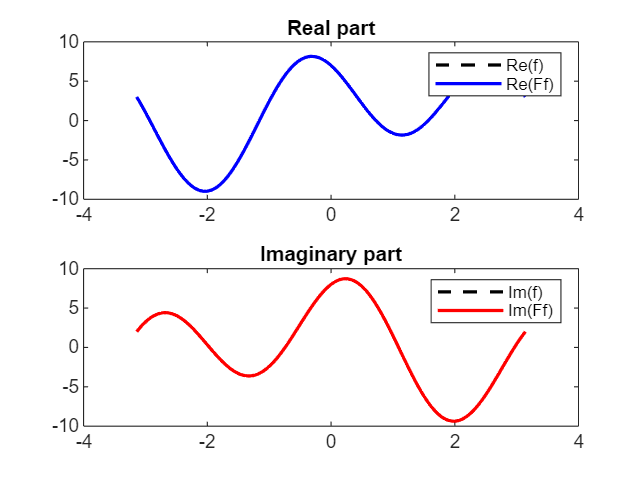

end

% Test
Ff = FourierSeries(fhat);
% Original function
f = @(x)(2+3i)*exp(-1i*x) + 1 + (4+5i)*exp(2i*x);

% Fourier coefficients
bw = 3;
fhat = FourierCoeff(f, bw);

% Reconstruct function
Ff = FourierSeries(fhat);

% Evaluate and plot
x = linspace(-pi, pi, 500);
fx = f(x);
fx_approx = Ff(x);


% Plot real parts
subplot(2,1,1);
plot(x, real(fx), 'k--', 'LineWidth', 1.5); hold on;
plot(x, real(fx_approx), 'b', 'LineWidth', 1.5);
legend('Re(f)', 'Re(Ff)');
title('Real part');

% Plot imaginary parts
subplot(2,1,2);
plot(x, imag(fx), 'k--', 'LineWidth', 1.5); hold on;
plot(x, imag(fx_approx), 'r', 'LineWidth', 1.5);
legend('Im(f)', 'Im(Ff)');
title('Imaginary part');

c) No we we want to test our Fourier approximation on various examples` f1, f2, f3, f4`.

How does the $2\pi$-periodization of this functions look like? Plot it!

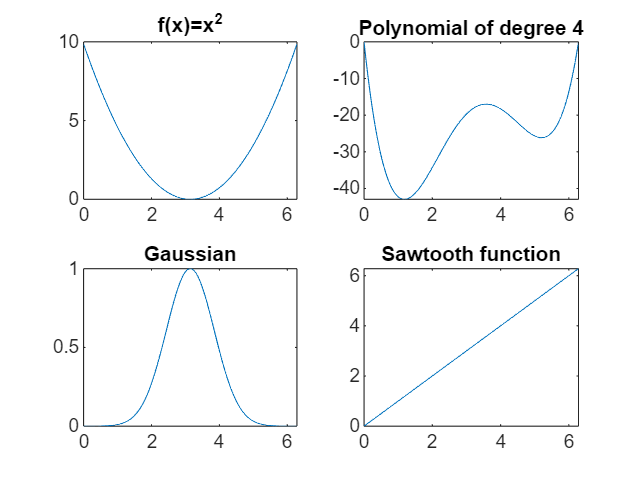

% Define example functions
f1 = @(x) (x-pi).^2;
f2 = @(x) x.*(x-2*pi).*(x.^2-7*x+14);
f3 = @(x) exp(-(x-pi).^2);
f4 = @(x) x;
% Plot
I = [0,2*pi];
x = (I(1):0.01:I(2));
figure
subplot(2,2,1)
plot(x,f1(mod(x,2*pi)))
title('f(x)=x^2')
xlim(I)

subplot(2,2,2)
plot(x,f2(mod(x,2*pi)))
title('Polynomial of degree 4')
xlim(I)



subplot(2,2,3)
plot(x,f3(mod(x,2*pi)))
title('Gaussian')
xlim(I);

subplot(2,2,4)
plot(x,f4(mod(x,2*pi)));
title("Sawtooth function");
xlim(I);

We want to test our Fourier approximation on this functions for various bandwidth $N$.

% Original function
f = @(x)(2+3i)*exp(-1i*x) + 1 + (4+5i)*exp(2i*x);

bw = 3


% Compute Fourier coefficients

Ff = function_handle with value:
    @(x)(exp(1i*x(:)*ks)*fhat)


bw = 3;
fhat = FourierCoeff(f, bw);

% Construct Fourier series
Ff = FourierSeries(fhat);

Ff

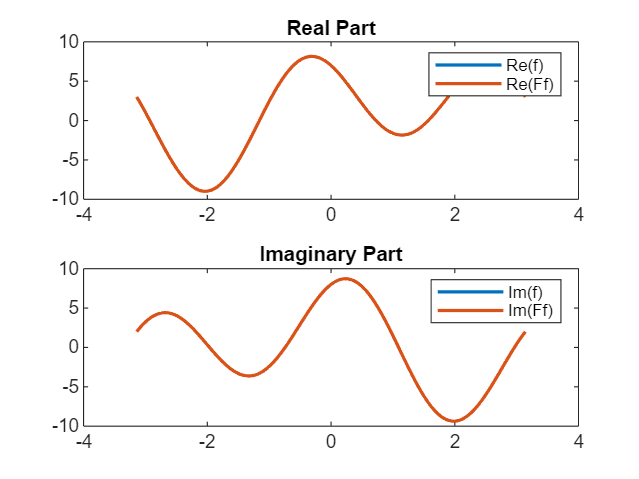

% Evaluate functions
x = linspace(-pi, pi, 500);   % row vector
fx = f(x);                    % row vector
fx_approx = Ff(x);            % column vector (after fix)

% Make them the same shape (column vectors)
fx = fx(:);         % force column
fx_approx = fx_approx(:);   % already column, but ensure it

% Plot real parts
subplot(2,1,1);
plot(x(:), [real(fx), real(fx_approx)], 'LineWidth', 1.5);
legend('Re(f)', 'Re(Ff)');

title('Real Part');

% Plot imaginary parts
subplot(2,1,2);
plot(x(:), [imag(fx), imag(fx_approx)], 'LineWidth', 1.5);
legend('Im(f)', 'Im(Ff)');
title('Imaginary Part');

d) Proof that the Fourier coefficients satisfy:

- $f$ is real valued   $\Rightarrow$    $\hat f_k = \overline{\hat f_{-k}}$

- $f$ is even             $\Rightarrow$    $\hat f_k = \hat f_{-k}$

What if $f$ is real valued and even?

Compile the following code to check the symmetry properties.

% Specify bandwidth
bw = 3;

% complex valued non symmetric function
fhat = FourierCoeff(@(x) f2(x)+1i*f4(x),bw)

fhat =    4.6867 - 0.5422i
   6.5563 - 0.9560i
   2.0451 - 4.7373i
 -23.7917 + 2.6928i
   0.1813 + 3.8397i
   5.8405 + 0.0584i
   4.4819 - 0.3554i


% real valued function
fhat = FourierCoeff(f2,bw)

fhat =    4.5843 - 0.0934i
   6.1984 - 0.5072i
   1.1132 - 4.2885i
 -23.7917 + 0.0000i
   1.1132 + 4.2885i
   6.1984 + 0.5072i
   4.5843 + 0.0934i


% even complex valued function
fhat = FourierCoeff(@(x) f1(x)+1i*f3(x),bw)

fhat =    0.4238 - 0.0246i
   0.6590 + 0.1032i
   2.1399 - 0.2197i
   3.4241 + 0.2821i
   2.1399 - 0.2197i
   0.6590 + 0.1032i
   0.4238 - 0.0246i


% even real valued function
fhat = FourierCoeff(@(x) f1(x),bw)u

fhat =    0.4238 + 0.0000i
   0.6590 + 0.0000i
   2.1399 - 0.0000i
   3.4241 + 0.0000i
   2.1399 + 0.0000i
   0.6590 - 0.0000i
   0.4238 - 0.0000i


### Exercise 2: (Convolution)

Now we want to investigate the relationship between convolution and fast Fourier transformation.

a)  In Multilevel smoothing an image is convolved with several Gaussian filters of different widths. 

We allready know, that the Gaussian filters are linear and therefore smoothing can be performed by convolution.

Since the convolution is distributive, we can model the convolution with several Gaussian kernels by convoluting with the convolution of them, i.e.

                          
$$f * g_{\sigma_1} * g_{\sigma_2} * ... g_{\sigma_n} = f * (g_{\sigma_1} * g_{\sigma_2}*...*g_{\sigma_n})$$


How does the resulting Filter look like?

The combination of these filters corresponds to the convolution of several Gaussian functions $g_{\sigma}(x) = \frac{1}{\sqrt{2\pi\sigma^2}} ~ \mathrm{e}^{-\frac{x^2}{2\sigma^2}}$

Compute $g_{\sigma_1} * g_{\sigma_2}$ by using the convolution theorem.

*Hint:* $g(x) = \frac1{\sqrt{2\pi\sigma^2}} ~ \mathrm e^{-\frac{x^2}{2\sigma^2}} $      $\longrightarrow$      $\hat g(\omega) = \mathrm e^{-\frac{\sigma^2\omega^2}2}$

b) One can compute the cyclic convolution of two vectors $x$ and $y$ by the matlab command` cconv()`.

x = 1:5

x =      1     2     3     4     5


y = [1 5 3 2 8]

y =      1     5     3     2     8


conv(x,y,"same")

ans =     16    27    46    59    47


z = cconv(x,y,5)

z =     60    54    58    67    46


Let $N$ be the length of the vectors $x$ and $y$. Then matlab computes every value of $z$ by a sum of length $N$. Hence the method has approximative complexity $O(N^2)$ , i.e. it needs around $c\cdot N^2$ computation steps with some fixed constant $c>0$.

Compute the cyclic convolution of $x$ and $y$ much faster with complexity $O(N\log N)$, i.e. use fast Fourier transforms.

*Hint:* Use the comands` fft `and` ifft`.

% TODO: compute cconv with fft
z=ifft(fft(x).*fft(y))

z =     60    54    58    67    46


c) The regular convolution, that is used by applying linear filters to images is computed by the command` conv()`.

z = conv(x,y)

z =      1     7    16    27    46    59    47    42    40


Compute the convolution of $x$ and $y$ much faster by using the fast Fourier transforms.

This is computing **circular convolution** using the **FFT (Fast Fourier Transform)**. It relies on the **convolution theorem**, which says:

**Circular convolution in time** = **Multiplication in frequency**

conv(x,y)=ifft(fft(x)⋅fft(y))

*Hint:* How do you use cyclic convolution to compute the regular convolution?

function z = convFFT(x,y)

z =     1.0000    7.0000   16.0000   27.0000   46.0000   59.0000   47.0000   42.0000   40.0000


z =     1.0000    7.0000   16.0000   27.0000   46.0000   59.0000   47.0000   42.0000   40.0000


% TODO: compute conv with fft
x1 = [x zeros(1,length(y)-1)];
y1 = [y zeros(1,length(x)-1)];
z = ifft(fft(x1).*fft(y1))
end
z = convFFT(x,y)

### Exercise 3: (Fourier transformed images)

In this exercise lots of images (left side) are given with there Fourier transform (right side). 

Take a close look at the pictures and try to interpret the results.

Note that we look on the absolute value of the Fourier transform (i.e. we examine how much of a specific frequency component is present). Moreover we use an logarithmic scale in the absolute values of the Fourier transfrom.

a) The center of the Fourier transformed image describes the mean average value of the image. 

Note that the following images are symmetric and real. What does that mean for there Fourier transform.

At first we take a look on the Fourier transform of the cosine function. Interpret!

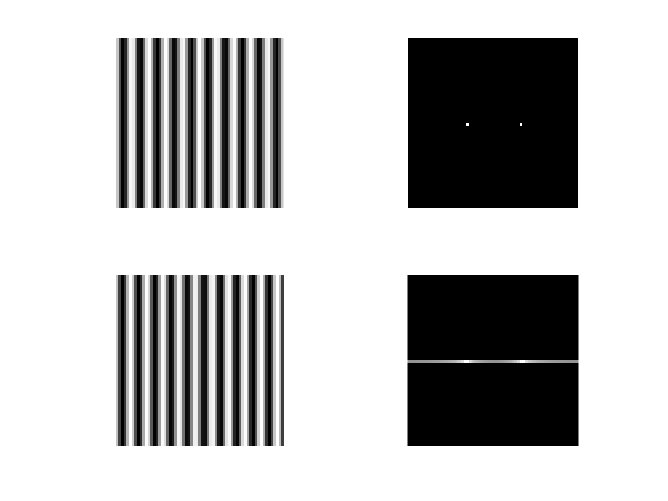

clear
% simulate images
[X,~] = meshgrid(0:63,0:63);
img1 = cos(10*2*pi*X/64);
img2 = cos(10.5*2*pi*X/64);

% compute the Fourier transforms
F1 = fftshift(fft2(img1));
F2 = fftshift(fft2(img2));

% plot
figure
subplot(2,2,1)
imshow(img1,[])
subplot(2,2,2)
imshow(log(1+abs(F1)),[])
subplot(2,2,3)
imshow(img2,[])
subplot(2,2,4)
imshow(log(1+abs(F2)),[])

b) Estimate what the Fourier transform of the following images might look like. 

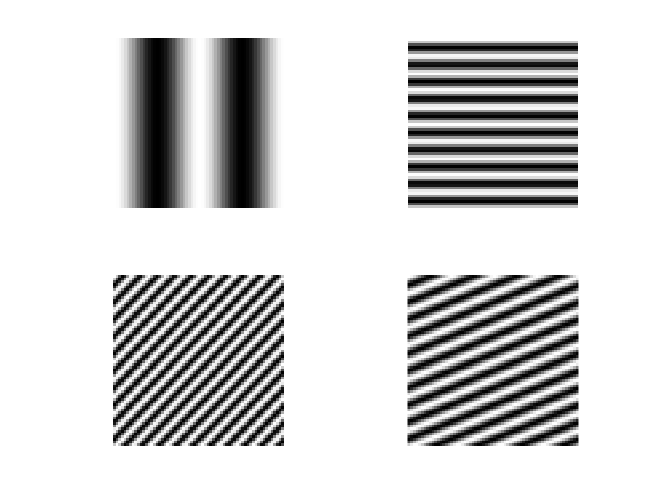

% Load and plot the images
load('imgFT.mat')
figure
for i = 1:4
  subplot(2,2,i)
  imshow(img{i},[])
end

Check your guesses by plotting the Fourier transforms.

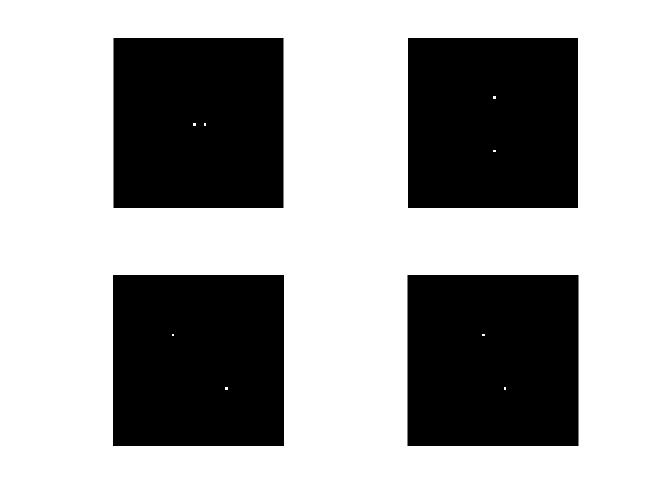

% Plot the Fourier transforms
figure
for i = 1:4
  subplot(2,2,i)
  F = fftshift(fft2(img{i}));
  imshow(log(1+abs(F)),[])
end

Now we examine step functions.

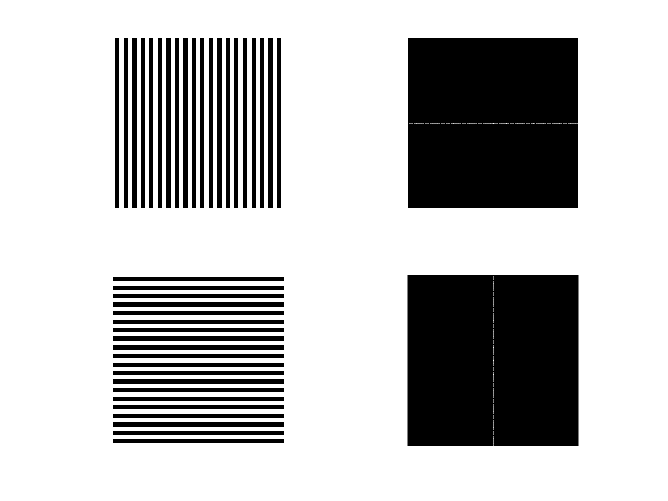

% Simulate images
[X,Y] = meshgrid(1:256,1:256);
img3 = round(0.5*cos(40*pi*(X)/256)+0.5);
img4 = round(0.5*cos(40*pi*(Y)/256)+0.5);

% compute the Fourier transforms
F3 = fftshift(fft2(img3));
F4 = fftshift(fft2(img4));

% plot
figure
subplot(2,2,1)
imshow(img3)
subplot(2,2,2)
imshow(log(1+abs(F3)),[])
subplot(2,2,3)
imshow(img4)
subplot(2,2,4)
imshow(log(1+abs(F4)),[])

What happens when we rotate the image?

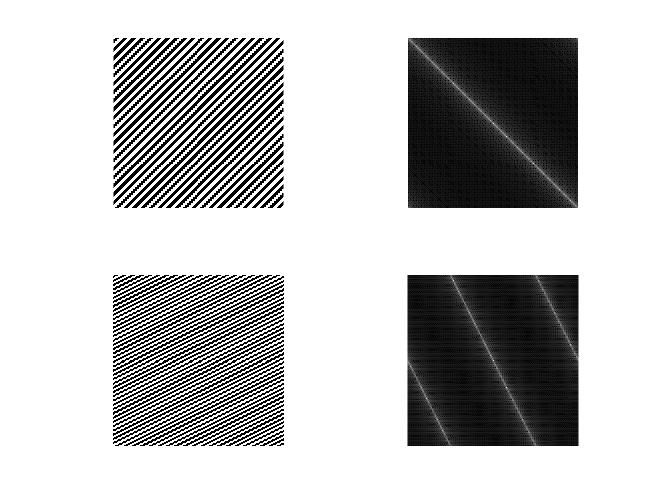

% Simulate images
img5 = round(0.5*cos(40*pi*(X+Y)/256)+0.5);
img6 = round(0.5*cos(40*pi*(X+2*Y)/256)+0.5);

% compute the Fourier transforms
F5 = fftshift(fft2(img5));
F6 = fftshift(fft2(img6));

% plot
figure
subplot(2,2,1)
imshow(img5)
subplot(2,2,2)
imshow(log(1+abs(F5)),[])
subplot(2,2,3)
imshow(img6)
subplot(2,2,4)
imshow(log(1+abs(F6)),[])

c) What does the Fourier transform say about edges in the image?

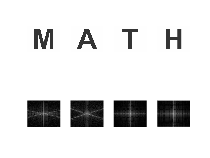

% load images
M = double(rgb2gray(imread('M.jpg')))/256;
A = double(rgb2gray(imread('A.jpg')))/256;
T = double(rgb2gray(imread('T.jpg')))/256;
H = double(rgb2gray(imread('H.jpg')))/256;

% compute Fourier transform
FM = fftshift(fft2(M));
FA = fftshift(fft2(A));
FT = fftshift(fft2(T));
FH = fftshift(fft2(H));

% plot
figure
subplot(2,4,1)
imshow(M)
subplot(2,4,5)
imshow(log(1+abs(FM)),[])
subplot(2,4,2)
imshow(A)
subplot(2,4,6)
imshow(log(1+abs(FA)),[])
subplot(2,4,3)
imshow(T)
subplot(2,4,7)
imshow(log(1+abs(FT)),[])
subplot(2,4,4)
imshow(H)
subplot(2,4,8)
imshow(log(1+abs(FH)),[])

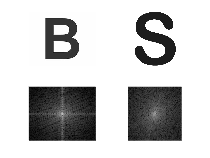

% load images
S = double(rgb2gray(imread('S.jpg')))/256;
B = double(rgb2gray(imread('B.jpg')))/256;

% Compute Fourier transform
FB = fftshift(fft2(B));
FS = fftshift(fft2(S));

% plot
figure
subplot(2,2,1)
imshow(B)
subplot(2,2,2)
imshow(S)
subplot(2,2,3)
imshow(log(1+abs(FB)),[])
subplot(2,2,4)
imshow(log(1+abs(FS)),[])

Also interpret the following natural images.

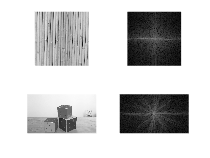

% load images
bamboo = double(rgb2gray(imread('bamboo.jpg')))/256;
cubes = double(rgb2gray(imread('rubix_cube.jpg')))/256;

% compute Fourier transform
Fbamboo = fftshift(fft2(bamboo));
Fcubes = fftshift(fft2(cubes));

% plot
figure
subplot(2,2,1)
imshow(bamboo)
subplot(2,2,2)
imshow(log(1+abs(Fbamboo)),[])
subplot(2,2,3)
imshow(cubes)
subplot(2,2,4)
imshow(log(1+abs(Fcubes)),[])

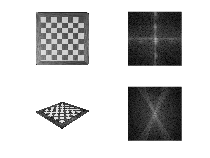

% load images
chess1 = double(rgb2gray(imread('chess1.jpg')))/256;
chess2 = double(rgb2gray(imread('chess2.png')))/256;

% compute Fourier transforms
Fchess1 = fftshift(fft2(chess1));
Fchess2 = fftshift(fft2(chess2));

% plot
figure
subplot(2,2,1)
imshow(chess1)
subplot(2,2,2)
imshow(log(1+abs(Fchess1)),[])
subplot(2,2,3)
imshow(chess2)
subplot(2,2,4)
imshow(log(1+abs(Fchess2)),[])

d) Take a look on the famous image processing test image` lena `from Playboy 1972. Why does the Fourier transformation of the image suggest edges similar to the previous images? Explain the “cross” at the axis.

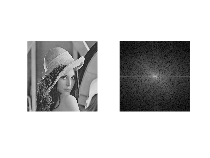

% load image
lena = double((imread('lena.png')))/256;

% compute Fourier transform
Flena = fftshift(fft2(lena));

% plot
figure
subplot(1,2,1)
imshow(lena)
subplot(1,2,2)
imshow(log(1+abs(Flena)),[])

e) We examine a random image. Why is there a white point in the middle of the Fourier transformed image?

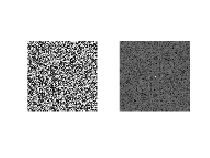

% simulate image
img5 = rand(64);

% Compute Fourier transform
F5 = fftshift(fft2(img5));

% plot
figure
subplot(1,2,1)
imshow(img5)
subplot(1,2,2)
imshow(log(1+abs(F5)),[])

### Exercise 4: (Locate Image Features)

We want to use the Fourier transform to perform correlation, which is closely related to convolution.

The Correlation can be used to locate features within the image.

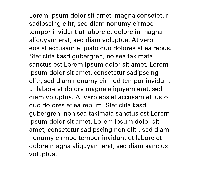

img = double(rgb2gray(imread('LoremIpsum.png')))/255;
imshow(img)

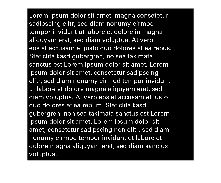

img = 1-img;
figure
imshow(img)

Create a template for matching by extracting the letter "a" from the image.

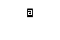

a = img(472:505,385:407);
imshow(a)

Compute the correlation of the template image with the original image by using the FFT-based convolution technique, i.e.

                                
$$( u \, \ast_p \, v)\hat{} = \hat u \cdot \overline{\hat v}$$


use the fft2 and ifft2 functions to match the template to the image. In the resulting image, the light peaks correspond to the occurrence of the letter.

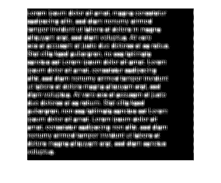

% TODO: Compute the correlation

c = ifft2(fft2(img).* conj(fft2(a,height(img),width(img))));
figure
imshow(c,[])

To view the locations of the template in the image, find the maximum pixel value and then define a threshold value that is less than this maximum. The thresholded image shows the locations of these peaks as white spots in the thresholded correlation image. (To make the locations easier to  see in this figure, the example dilates the thresholded image to enlarge the size of the points.)

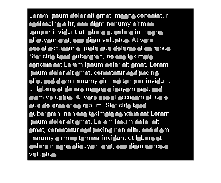

% shift to center of letters a
c = circshift(c,round((height(a)-1)/2),1);
c = circshift(c,round((width(a)-1)/2),2);

% Plot the maximal values of the correlation matrix
m = max(abs(c(:)));
A = imdilate(c > m*0.9,strel('disk',10));
img(A) = 0.7;

figure
imshow(img)